close all; clear; clc;

# P80 characterization tests 4 bat STv2 ALL cont. recording tests

(10% throttle to 90% throttle multiple times  **- Record all**)

**file name**: STv2_P8027d_20181115_1.mlx

**keywords:** 

**date of test:** 20180928

**file created by:** 20181001, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

% Air Density
p = 0.002377;                  %[slugs/ft^3]
% If this wasn't recorded on the day of the test use 0.00228344448402635. 
% Record this in the notes section above

% Motor Specs
radius = 27/12;               % [ft]
area = pi * radius^(2);       % [ft^2]

## Measured Data- Test 1

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_P8027d_20181115_1.mat');
time1 = STv2_P8027d_20181115_1(:,1);                       % [sec]
PWM1 = STv2_P8027d_20181115_1(:,2);                        % [micro sec]
Q1 = STv2_P8027d_20181115_1(:,4);                          % [ft.lbf]
T1 = STv2_P8027d_20181115_1(:,5);                          % [lbf]
Input_V1 = STv2_P8027d_20181115_1(:,6);                    % [Volts]
Input_A1 = STv2_P8027d_20181115_1(:,7);                    % [Amps]
rot_speed_rpm1 = STv2_P8027d_20181115_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad1 = rot_speed_rpm1 .* (pi/30);   % [rad/sec]
P_in_W1 = STv2_P8027d_20181115_1(:,9);                     % [Watts]
P_out_W1 = STv2_P8027d_20181115_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out1 = P_out_W1 .* 0.7478;                  % [ft.lbf/sec]         
P_in1 = P_in_W1 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff1 = STv2_P8027d_20181115_1(:,11);                 % [%]
Prop_Eff1 = STv2_P8027d_20181115_1(:,12);                  % [lbf/Watts]
Overall_Eff1 = STv2_P8027d_20181115_1(:,13);               % [lbf/Watts]  
ESC_Temp1 = STv2_P8027d_20181115_1(:,14);                  % [F]
Motor_Temp1 = STv2_P8027d_20181115_1(:,15);                % [F]

disk_loading1 = T1 ./ area;                     % [lb/sq.ft]

Settling_time1 = STv2_P8027d_20181115_1(:,17); % [s]
Max_Acc1 = STv2_P8027d_20181115_1(:,18);      % [RPM]

C_T1 = T1 ./ (p .* area * (rot_speed_rad1 * radius).^2);
C_P1 = P_out1 ./ (p .* area .* (rot_speed_rad1 .* radius).^3);
C_Q1 = Q1 ./ (p .* area .* (rot_speed_rad1 .* radius).^(2) .* radius);

throttle1 = (PWM1 - 1000) ./ 10;

## Measured Data - Test 2

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_P8027d_20181115_2.mat');
time2 = STv2_P8027d_20181115_2(:,1);                       % [sec]
PWM2 = STv2_P8027d_20181115_2(:,2);                        % [micro sec]
Q2 = STv2_P8027d_20181115_2(:,4);                          % [ft.lbf]
T2 = STv2_P8027d_20181115_2(:,5);                          % [lbf]
Input_V2 = STv2_P8027d_20181115_2(:,6);                    % [Volts]
Input_A2 = STv2_P8027d_20181115_2(:,7);                    % [Amps]
rot_speed_rpm2 = STv2_P8027d_20181115_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad2 = rot_speed_rpm2 .* (pi/30);   % [rad/sec]
P_in_W2 = STv2_P8027d_20181115_2(:,9);                     % [Watts]
P_out_W2 = STv2_P8027d_20181115_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out2 = P_out_W2 .* 0.7478;                  % [ft.lbf/sec]         
P_in2 = P_in_W2 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff2 = STv2_P8027d_20181115_2(:,11);                 % [%]
Prop_Eff2 = STv2_P8027d_20181115_2(:,12);                  % [lbf/Watts]
Overall_Eff2 = STv2_P8027d_20181115_2(:,13);               % [lbf/Watts]  
ESC_Temp2 = STv2_P8027d_20181115_2(:,14);                  % [F]
Motor_Temp2 = STv2_P8027d_20181115_2(:,15);                % [F]

disk_loading2 = T2 ./ area;                     % [lb/sq.ft]

Settling_time2 = STv2_P8027d_20181115_2(:,17); % [s]
Max_Acc2 = STv2_P8027d_20181115_2(:,18);      % [RPM]

C_T2 = T2 ./ (p .* area * (rot_speed_rad2 * radius).^2);
C_P2 = P_out2 ./ (p .* area .* (rot_speed_rad2 .* radius).^3);
C_Q2 = Q2 ./ (p .* area .* (rot_speed_rad2 .* radius).^(2) .* radius);

throttle2 = (PWM2 - 1000) ./ 10;

## Measured Data

This format assumes that the data output from RC Benchmark has not been changed

load('STv2_P8027d_20181115_3.mat');
time3 = STv2_P8027d_20181115_3(:,1);                       % [sec]
PWM3 = STv2_P8027d_20181115_3(:,2);                        % [micro sec]
Q3 = STv2_P8027d_20181115_3(:,4);                          % [ft.lbf]
T3 = STv2_P8027d_20181115_3(:,5);                          % [lbf]
Input_V3 = STv2_P8027d_20181115_3(:,6);                    % [Volts]
Input_A3 = STv2_P8027d_20181115_3(:,7);                    % [Amps]
rot_speed_rpm3 = STv2_P8027d_20181115_3(:,8);              % [RPM]
% convert to RPM for plotting purposes
rot_speed_rad3 = rot_speed_rpm3 .* (pi/30);   % [rad/sec]
P_in_W3 = STv2_P8027d_20181115_3(:,9);                     % [Watts]
P_out_W3 = STv2_P8027d_20181115_3(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out3 = P_out_W3 .* 0.7478;                  % [ft.lbf/sec]         
P_in3 = P_in_W3 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff3 = STv2_P8027d_20181115_3(:,11);                 % [%]
Prop_Eff3 = STv2_P8027d_20181115_3(:,12);                  % [lbf/Watts]
Overall_Eff3 = STv2_P8027d_20181115_3(:,13);               % [lbf/Watts]  
ESC_Temp3 = STv2_P8027d_20181115_3(:,14);                  % [F]
Motor_Temp3 = STv2_P8027d_20181115_3(:,15);                % [F]

disk_loading3 = T3 ./ area;                     % [lb/sq.ft]

Settling_time3 = STv2_P8027d_20181115_3(:,17); % [s]
Max_Acc3 = STv2_P8027d_20181115_3(:,18);      % [RPM]

C_T3 = T3 ./ (p .* area * (rot_speed_rad3 * radius).^2);
C_P3 = P_out3 ./ (p .* area .* (rot_speed_rad3 .* radius).^3);
C_Q3 = Q3 ./ (p .* area .* (rot_speed_rad3 .* radius).^(2) .* radius);

throttle3 = (PWM3 - 1000) ./ 10;

## Plots

The following are standard charts. Remove, add, and edit as needed.

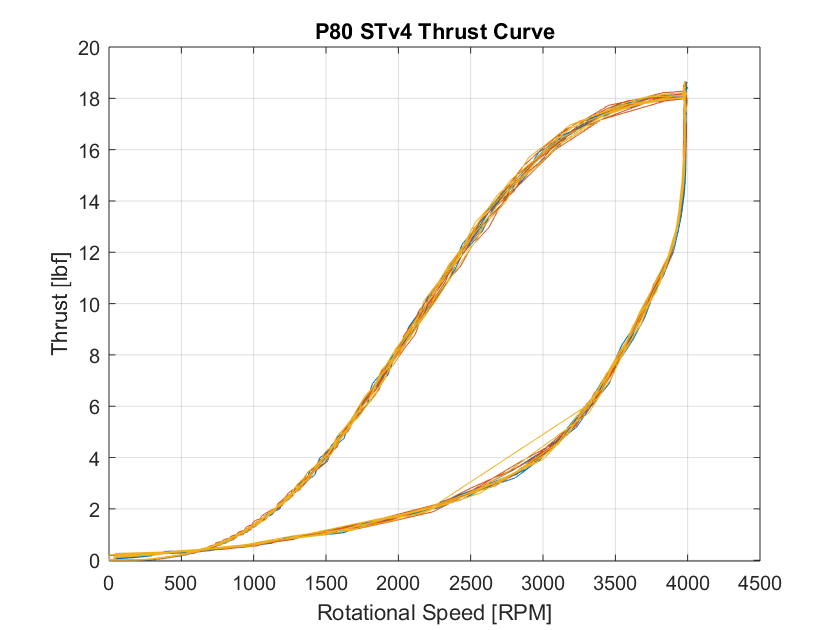

figure(1)
plot(rot_speed_rpm1, T1, rot_speed_rpm2, T2, rot_speed_rpm3, T3); title('P80 STv4 Thrust Curve'); 
xlabel('Rotational Speed [RPM]'); ylabel('Thrust [lbf]'); grid('on');

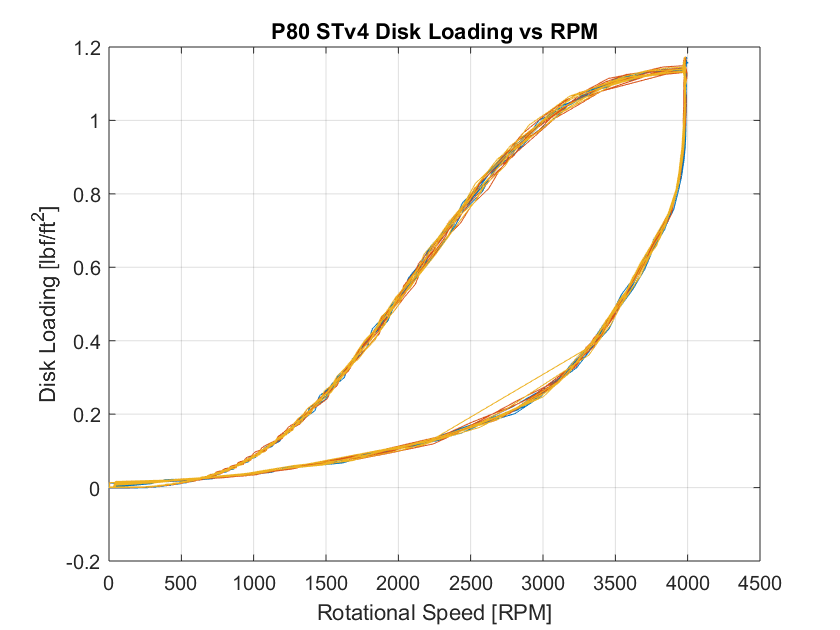


figure(2)
plot(rot_speed_rpm1, disk_loading1, rot_speed_rpm2, disk_loading2, rot_speed_rpm3, disk_loading3); title('P80 STv4 Disk Loading vs RPM');
xlabel('Rotational Speed [RPM]'); ylabel('Disk Loading [lbf/ft^2]')
grid('on');

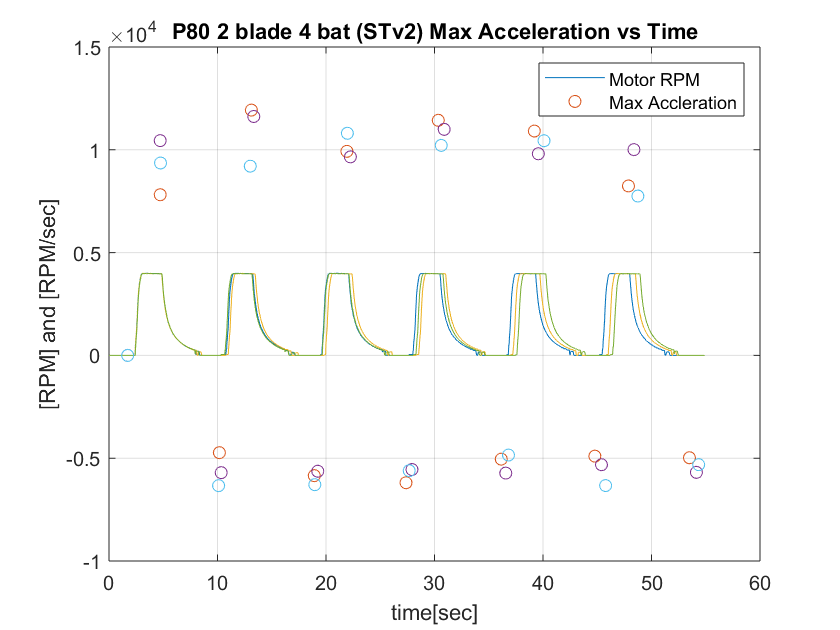


figure(3)
plot(time1, rot_speed_rpm1, time1, Max_Acc1, 'o', time2, rot_speed_rpm2, time2, Max_Acc2, 'o', time3, rot_speed_rpm3, time3, Max_Acc3, 'o');
title('P80 2 blade 4 bat (STv2) Max Acceleration vs Time')
xlabel('time[sec]'); ylabel('[RPM] and [RPM/sec]'); 
legend('Motor RPM', 'Max Accleration'); grid('on');
ylim([-1E4 1.5E4]);

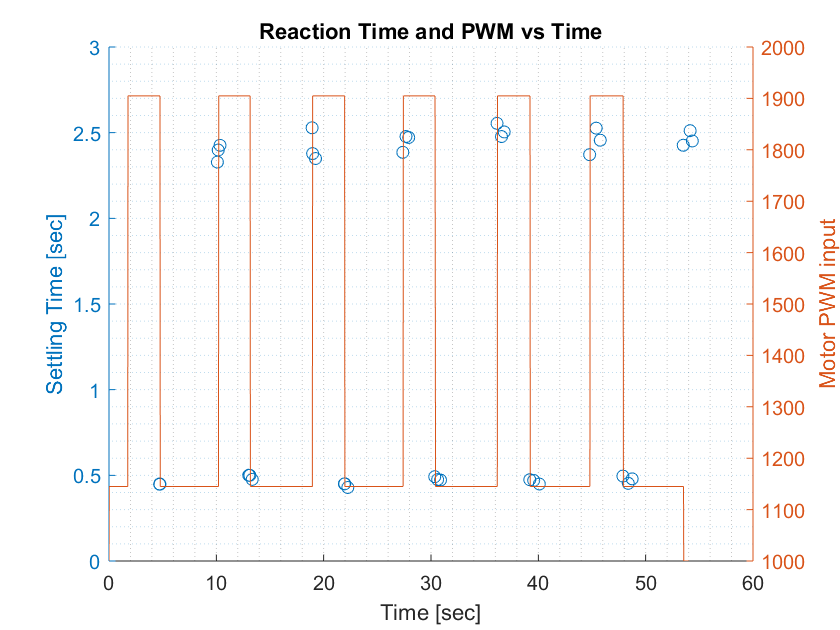


figure(4)
hold on
yyaxis left
plot(time1,Settling_time1, 'o-', time2,Settling_time2, 'o-', time3,Settling_time3, 'o-');
ylabel('Settling Time [sec]');
yyaxis right
plot(time1, PWM1);
ylabel('Motor PWM input');
title('Reaction Time and PWM vs Time');
xlabel('Time [sec]');
grid('minor');
hold off

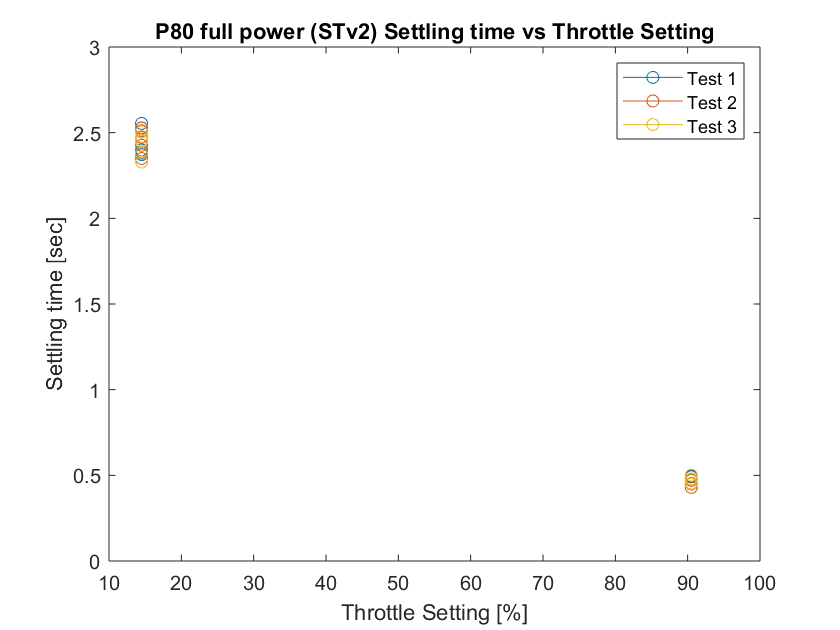


figure(5)
plot(throttle1, Settling_time1, 'o-', throttle2, Settling_time2, 'o-', throttle3, Settling_time3, 'o-');
title('P80 full power (STv2) Settling time vs Throttle Setting');
xlabel('Throttle Setting [%]'); ylabel('Settling time [sec]');
legend('Test 1', 'Test 2', 'Test 3');

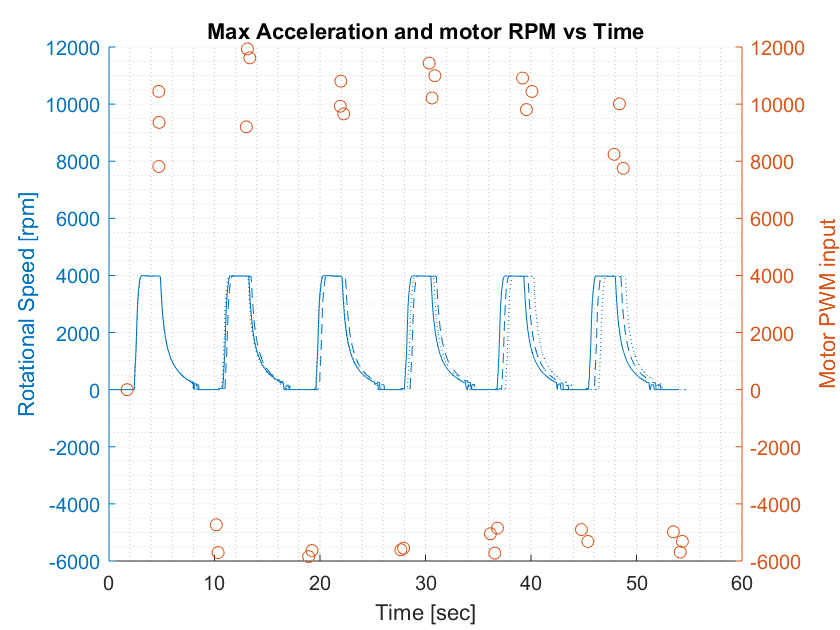


figure(6)
hold on
yyaxis left
plot(time1, rot_speed_rpm1, time2, rot_speed_rpm2, time3, rot_speed_rpm3);
ylabel('Rotational Speed [rpm]');
ylim([-6000 12000]);
yyaxis right
plot(time1, Max_Acc1, 'o-', time2, Max_Acc2, 'o-', time3, Max_Acc3, 'o-');
ylabel('Motor PWM input');
title('Max Acceleration and motor RPM vs Time');
ylim([-6000 12000]);
xlabel('Time [sec]');
grid('minor');
hold off